% load the module data for 120 reps on R = 5, earlyStop = 60
% if it is of the full length, we need to set earlyStop = 100 with
% moduleResultfull.mat
clear; close all;
epochEarlystop = 100;

parfor i = 1:120
    i
    folderName_R_5_rep_120_diff_data{i} = sprintf('r_5_rep_120_diff_data/%d',i);
    dataFile_R_5_rep_120_diff_data{i} = load(sprintf('data/%s/moduleResultFull.mat',folderName_R_5_rep_120_diff_data{i}));
end

ans = 120

ans = 119

ans = 118

ans = 117

ans = 116

ans = 115

ans = 114

ans = 113

ans = 112

ans = 111

ans = 110

ans = 109

ans = 108

ans = 107

ans = 106

ans = 105

ans = 104

ans = 103

ans = 102

ans = 101

ans = 100

ans = 99

ans = 98

ans = 97

ans = 96

ans = 95

ans = 94

ans = 93

ans = 92

ans = 91

ans = 90

ans = 89

ans = 88

ans = 87

ans = 86

ans = 85

ans = 84

ans = 83

ans = 82

ans = 81

ans = 80

ans = 79

ans = 78

ans = 77

ans = 76

ans = 75

ans = 74

ans = 73

ans = 72

ans = 71

ans = 70

ans = 69

ans = 68

ans = 67

ans = 66

ans = 65

ans = 64

ans = 63

ans = 62

ans = 61

ans = 60

ans = 59

ans = 58

ans = 57

ans = 56

ans = 55

ans = 54

ans = 53

ans = 52

ans = 51

ans = 50

ans = 49

ans = 48

ans = 47

ans = 46

ans = 45

ans = 44

ans = 43

ans = 42

ans = 41

ans = 40

ans = 39

ans = 38

ans = 37

ans = 36

ans = 35

ans = 34

ans = 33

ans = 32

ans = 31

ans = 30

ans = 29

ans = 28

ans = 27

ans = 26

ans = 25

ans = 24

ans = 23

ans = 22

ans = 21

ans = 20

ans = 19

ans = 18

ans = 17

ans = 16

ans = 15

ans = 14

ans = 13

ans = 12

ans = 11

ans = 10

ans = 9

ans = 8

ans = 7

ans = 6

ans = 5

ans = 4

ans = 3

ans = 2

ans = 1

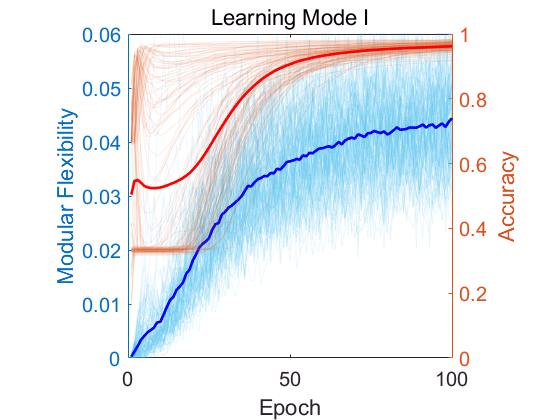

% examine the two types of learning curve separately
% plot Type I: warm-up-then-increase
load('accuTypeMannual.mat');
flex_stack = [];
modu_stack = [];
nCommunity_stack = [];
acc_stack = [];
numInstance = 120;

for i = 1:numInstance
    % save the network measurement for each instance
    modu_stack = cat(2, modu_stack, dataFile_R_5_rep_120_diff_data{i}.modularity(1:epochEarlystop));
    nCommunity_stack = cat(2, nCommunity_stack, dataFile_R_5_rep_120_diff_data{i}.nCommunity(1:epochEarlystop));
    flex_stack = cat(2, flex_stack, dataFile_R_5_rep_120_diff_data{i}.flexibility(1:epochEarlystop));
    acc_stack = cat(2, acc_stack, dataFile_R_5_rep_120_diff_data{i}.acc(1:epochEarlystop));
    
end

% load and preprocess the entropy data into two types
load('entropyData.mat');
entropy_stack = entropy_stack(1:epochEarlystop,:);
type_1_ent_stack = entropy_stack(:, accCurveType ==1);
% plot the two types of curves and their average: flex and accuracy

figure;
title('Learning Mode I')
accCurveType = ones(120,1);
yyaxis left;
type_1_flex_stack = [];
type_1_acc_stack = [];
type_1_modu_stack = [];
type_1_eta_stack = [];
type_1_stationarity_stack = [];
type_1_nCommunity_stack = [];
for i = 1:120
    if accCurveType(i) == 1
        ll = plot(dataFile_R_5_rep_120_diff_data{i}.flexibility(1:epochEarlystop),'cyan'); 
        ll.Color = [0.3010, 0.7450, 0.9330, 0.1];hold on;
        type_1_flex_stack = cat(2,type_1_flex_stack, dataFile_R_5_rep_120_diff_data{i}.flexibility(1:epochEarlystop));
        type_1_modu_stack = cat(2,type_1_modu_stack, dataFile_R_5_rep_120_diff_data{i}.modularity(1:epochEarlystop));
        type_1_eta_stack = cat(2,type_1_eta_stack, dataFile_R_5_rep_120_diff_data{i}.eta(1:epochEarlystop));
        type_1_stationarity_stack = cat(2, type_1_stationarity_stack, dataFile_R_5_rep_120_diff_data{i}.stationarity(1:epochEarlystop));
        type_1_nCommunity_stack = cat(2, type_1_nCommunity_stack, dataFile_R_5_rep_120_diff_data{i}.nCommunity(1:epochEarlystop));
  
    end
end
plot(mean(type_1_flex_stack,2),'blue','LineWidth',2);
ylim([0,0.06]);
ylabel('Modular Flexibility');
% xlabel('epoch');
% subplot(1,2,2);
yyaxis right;
for i = 1:120
    if accCurveType(i) == 1
        lr = plot(dataFile_R_5_rep_120_diff_data{i}.acc(1:epochEarlystop),'cyan'); 
        lr.Color = [0.8500, 0.3250, 0.0980, 0.1];  hold on;
        type_1_acc_stack = cat(2, type_1_acc_stack, dataFile_R_5_rep_120_diff_data{i}.acc(1:epochEarlystop));
    end
end
plot(mean(type_1_acc_stack,2),'red','LineWidth',2);
ylim([0,1]);
ylabel('Accuracy');
xlabel('Epoch');
set(gca,'FontSize',15);
axis square;

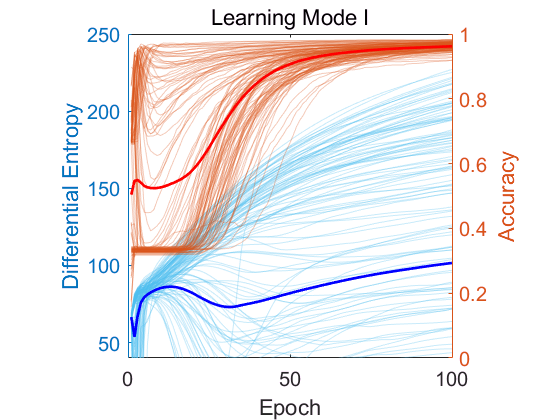



figure;
yyaxis left;
plot((1:epochEarlystop)*10, mean(type_1_flex_stack,2),'blue','LineWidth',2);
% ylim([0,0.06]);
ylabel('Flexibility');
yyaxis right;
plot((1:epochEarlystop)*10, mean(type_1_acc_stack,2),'red','LineWidth',2);
% ylim([0,1]);
ylabel('Accuracy');
xlabel('Epoch');
set(gca,'FontSize',15);
axis square;








% plot the two types of curves and their average: entropy and accuracy
figure;
title('Learning Mode I')
yyaxis left;
for i = 1:120
    if accCurveType(i) == 1
        ll = plot(entropy_stack(:,i),'cyan'); 
        ll.Color = [0.3010, 0.7450, 0.9330, 0.3];hold on;
    end
end
plot(mean(type_1_ent_stack,2),'blue','LineWidth',2);
ylim([40,250]);
ylabel('Differential Entropy');
% xlabel('epoch');
% subplot(1,2,2);
yyaxis right;
for i = 1:120
    if accCurveType(i) == 1
        lr = plot(dataFile_R_5_rep_120_diff_data{i}.acc(1:epochEarlystop),'cyan'); 
        lr.Color = [0.8500, 0.3250, 0.0980, 0.3];  hold on;
    end
end
plot(mean(type_1_acc_stack,2),'red','LineWidth',2);
ylim([0,1]);
ylabel('Accuracy');
xlabel('Epoch');
set(gca,'FontSize',15);
axis square;

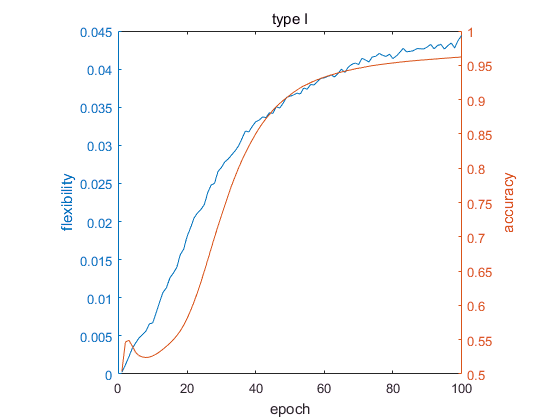



% plot flexibility & accuracy
figure;
yyaxis left;
plot(mean(type_1_flex_stack,2));
ylabel('flexibility')
yyaxis right;
plot(mean(type_1_acc_stack,2));
ylabel('accuracy')
title('type I');
xlabel('epoch');
axis square;

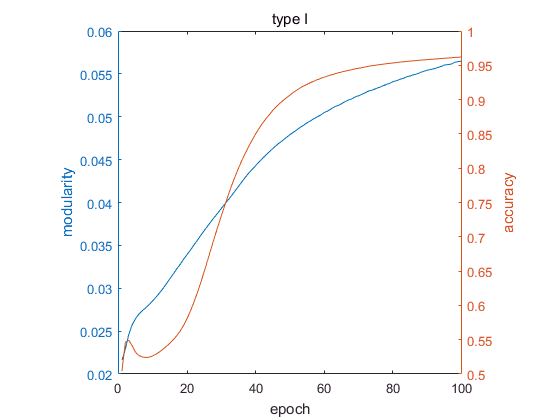


% plot modularity & accuracy
figure;
yyaxis left;
plot(mean(type_1_modu_stack,2));
ylabel('modularity')
yyaxis right;
plot(mean(type_1_acc_stack,2));
ylabel('accuracy')
title('type I');
xlabel('epoch');
axis square;

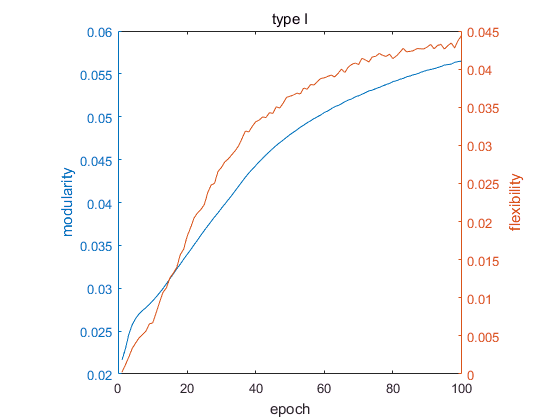


% plot modularity & flexibility
figure;
yyaxis left;
plot(mean(type_1_modu_stack,2));
ylabel('modularity')
yyaxis right;
plot(mean(type_1_flex_stack,2));
ylabel('flexibility')
title('type I');
xlabel('epoch');
axis square;

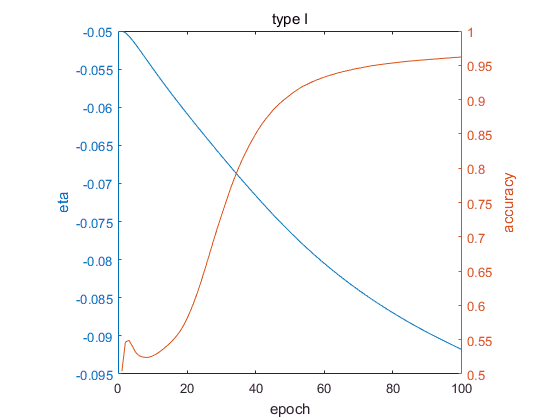



% plot eta & accuracy
figure;
yyaxis left;
plot(mean(type_1_eta_stack,2));
ylabel('eta')
yyaxis right;
plot(mean(type_1_acc_stack,2));
ylabel('accuracy')
title('type I');
xlabel('epoch');
axis square;

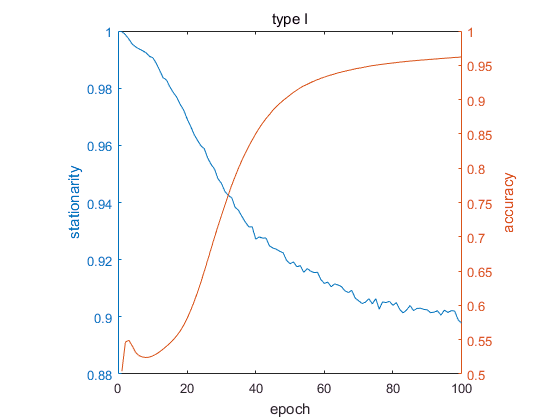



% plot stationarity & accuracy
figure;
yyaxis left;
plot(mean(type_1_stationarity_stack,2));
ylabel('stationarity')
yyaxis right;
plot(mean(type_1_acc_stack,2));
ylabel('accuracy')
title('type I');
xlabel('epoch');
axis square;

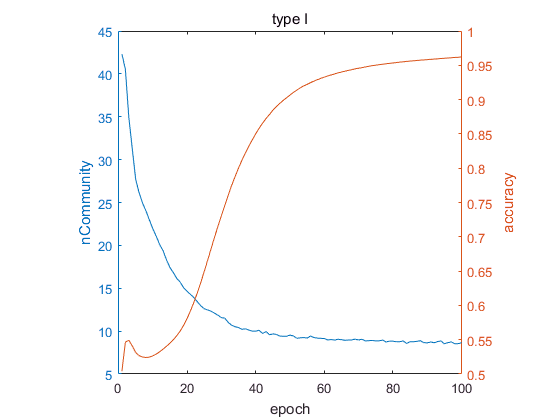


% plot nCommunity & accuracy
figure;
yyaxis left;
plot(mean(type_1_nCommunity_stack,2));
ylabel('nCommunity')
yyaxis right;
plot(mean(type_1_acc_stack,2));
ylabel('accuracy')
title('type I');
xlabel('epoch');
axis square;

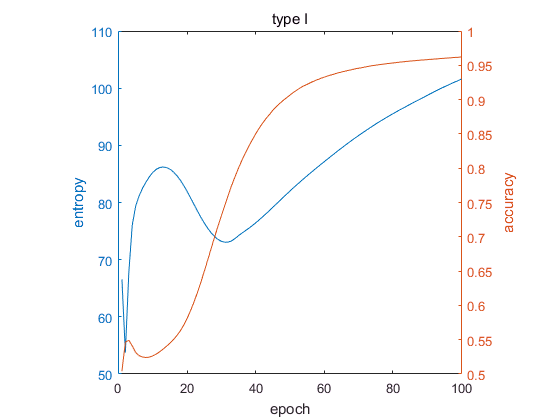


% plot entropy & accuracy
figure;
yyaxis left;
plot(mean(type_1_ent_stack,2));
ylabel('entropy')
yyaxis right;
plot(mean(type_1_acc_stack,2));
ylabel('accuracy')
title('type I');
xlabel('epoch');
axis square;

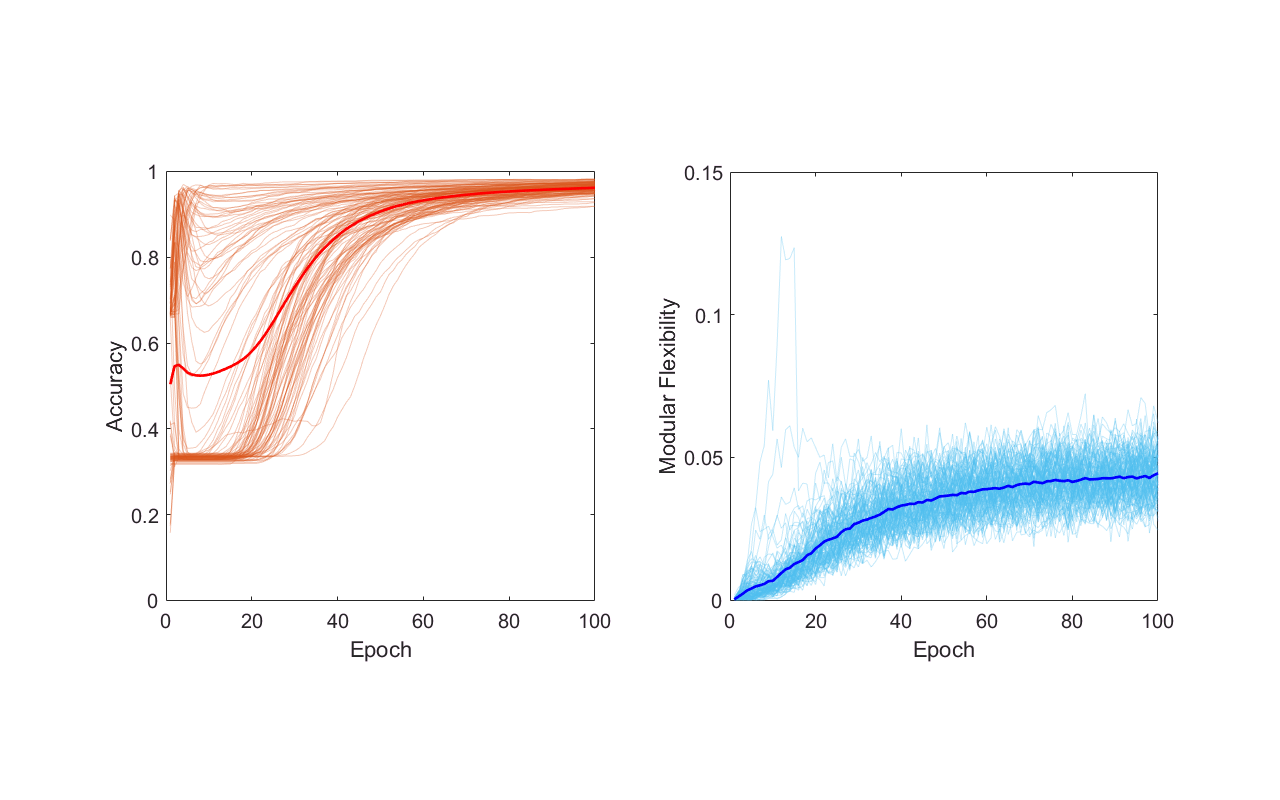


% plot accuracy, flexibility, module size, and entropy in a 2x4 panel
figure;
set(gcf,'position',[0,0,1280,800]); 
subplot(1,2,1);
title('Learning Mode I')
for i = 1:120
    if accCurveType(i) == 1
        lr = plot(dataFile_R_5_rep_120_diff_data{i}.acc(1:epochEarlystop),'cyan'); 
        lr.Color = [0.8500, 0.3250, 0.0980, 0.3];  hold on;
    end
end
plot(mean(type_1_acc_stack,2),'red','LineWidth',2);
ylim([0,1]);
ylabel('Accuracy');
xlabel('Epoch');
set(gca,'FontSize',15);
axis square;

subplot(1,2,2);
title('Learning Mode I')
for i = 1:120
    if accCurveType(i) == 1
        ll = plot(dataFile_R_5_rep_120_diff_data{i}.flexibility(1:epochEarlystop),'cyan'); 
        ll.Color = [0.3010, 0.7450, 0.9330, 0.3];hold on;
    end
end
plot(mean(type_1_flex_stack,2),'blue','LineWidth',2);
ylim([0,0.15]);
ylabel('Modular Flexibility');
xlabel('Epoch');
set(gca,'FontSize',15);
axis square;

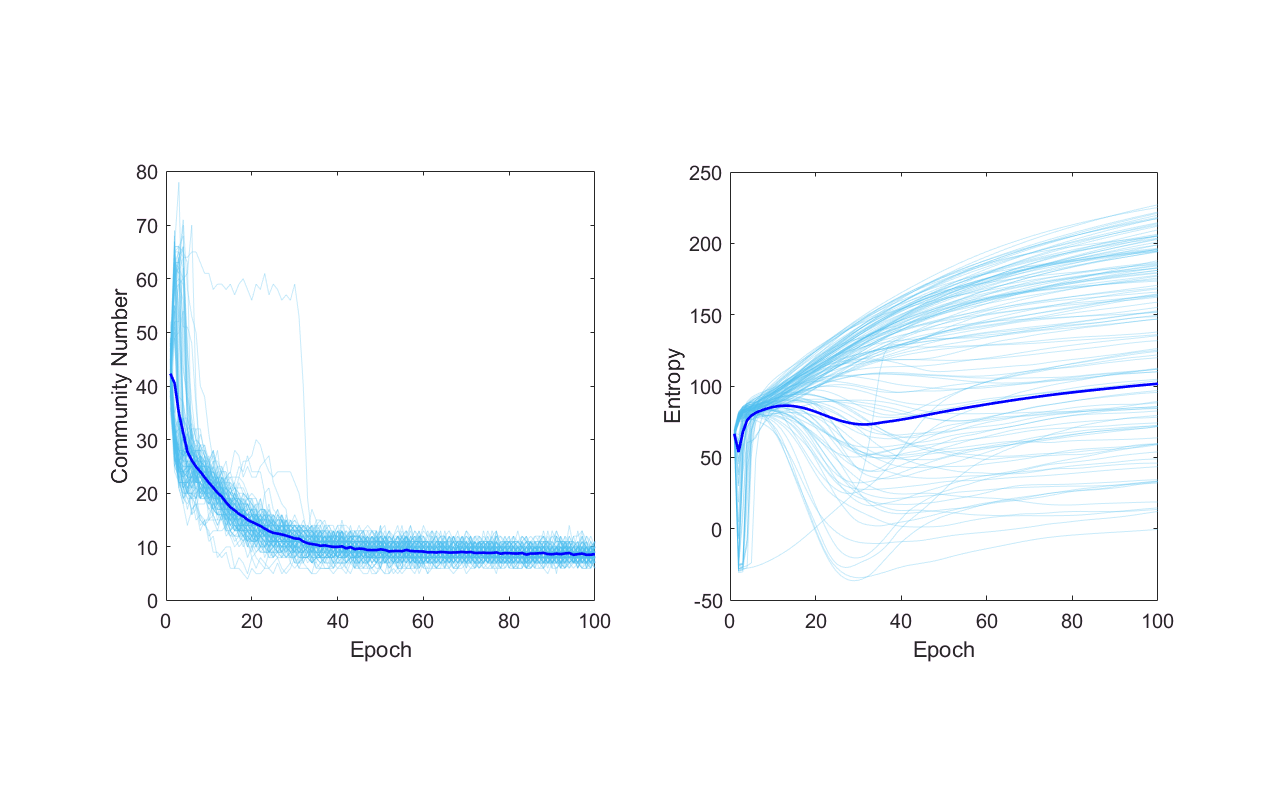


figure;
set(gcf,'position',[0,0,1280,800]); 
subplot(1,2,1);
title('Learning Mode I')
for i = 1:120
    if accCurveType(i) == 1
        ll = plot(dataFile_R_5_rep_120_diff_data{i}.nCommunity(1:epochEarlystop),'cyan'); 
        ll.Color = [0.3010, 0.7450, 0.9330, 0.3];hold on;
    end
end
plot(mean(type_1_nCommunity_stack,2),'blue','LineWidth',2);
ylim([0,80]);
ylabel('Community Number');
xlabel('Epoch');
set(gca,'FontSize',15);
axis square;

subplot(1,2,2);
title('Learning Mode I')
for i = 1:120
    if accCurveType(i) == 1
        ll = plot(entropy_stack(:,i),'cyan'); 
        ll.Color = [0.3010, 0.7450, 0.9330, 0.3];hold on;
    end
end
plot(mean(type_1_ent_stack,2),'blue','LineWidth',2);
ylim([-50,250]);
ylabel('Entropy');
xlabel('Epoch');
set(gca,'FontSize',15);
axis square;

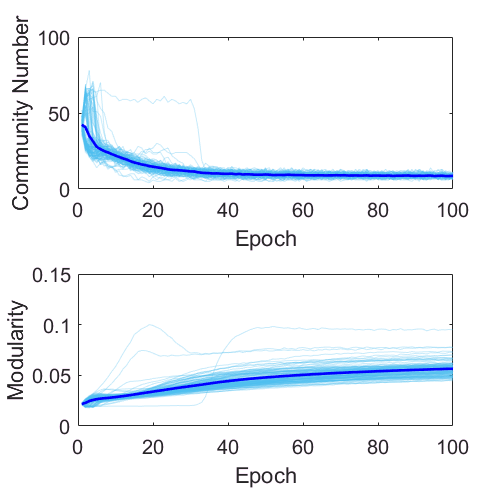



% plot the modular properties
figure;
set(gcf,'position',[0,0,500,500]); 
subplot(2,1,1);
for i = 1:120
    ll = plot(dataFile_R_5_rep_120_diff_data{i}.nCommunity(1:epochEarlystop),'cyan'); 
    ll.Color = [0.3010, 0.7450, 0.9330, 0.3];hold on;
end
plot(mean(nCommunity_stack,2),'blue','LineWidth',2);
ylabel('Community Number');
xlabel('Epoch');
set(gca,'FontSize',15);
% axis square;

subplot(2,1,2);
for i = 1:120
    ll = plot(modu_stack(:,i),'cyan'); 
    ll.Color = [0.3010, 0.7450, 0.9330, 0.3];hold on;
end
plot(mean(modu_stack,2),'blue','LineWidth',2);
ylabel('Modularity');
xlabel('Epoch');
set(gca,'FontSize',15);

% axis square;


% visualize the special case
%{
for idx = 1:120
    figure;
    yyaxis left;
    plot(flex_stack(:,idx),'LineWidth',2);
    ylabel('flexibility')
    yyaxis right;
    plot(acc_stack(:,idx),'LineWidth',2);
    ylabel('accuracy')
    title('type I');
    xlabel('epoch');
    axis square;
    set(gca,'FontSize',15);
end
%}

% calculate the correlation between modularity and flexibilty with accuracy, over samples and instances
% flex_acc_corr_sample = zeros(120,epochEarlystop);
% flex_acc_corr_instance = zeros(120, epochEarlystop);
% for i = 1:120
%     for j = 1:epochEarlystop
%        flex_acc_corr_sample(i,j) = 
%    end
% end




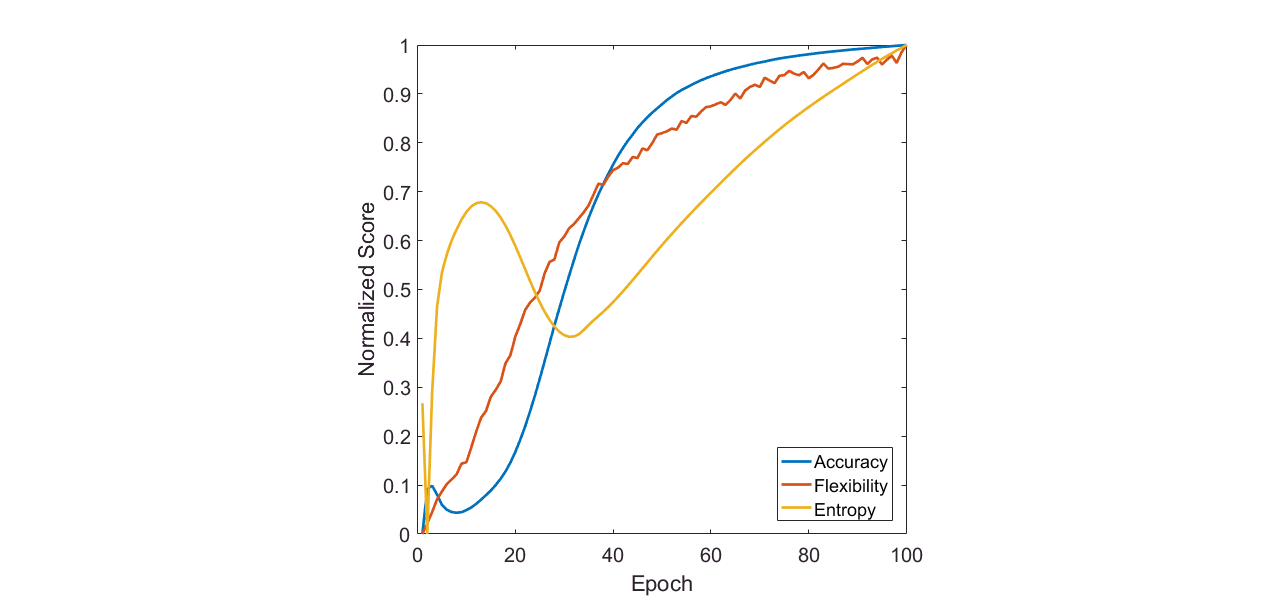

% plot the accuracy, flex, nCommunity, and entropy in a single figure for the two modes
type_1_acc_flex_nComm_ent = [mean(type_1_acc_stack,2), mean(type_1_flex_stack,2), mean(type_1_ent_stack,2)];

type_1_acc_flex_nComm_ent_rescale = zeros(size(type_1_acc_flex_nComm_ent));


for i = 1:3
    type_1_acc_flex_nComm_ent_rescale(:,i) = normalize_zero_one(type_1_acc_flex_nComm_ent(:,i));
end
curveLegend = {'Accuracy', 'Flexibility', 'Entropy'};
figure;
set(gcf,'position',[0,0,1280,600]); 
title('Learning Mode I');
plot(type_1_acc_flex_nComm_ent_rescale,'LineWidth',2);
xlabel('Epoch');
ylabel('Normalized Score');
legend(curveLegend, 'Location','southeast');
axis square;
set(gca,'FontSize',15);

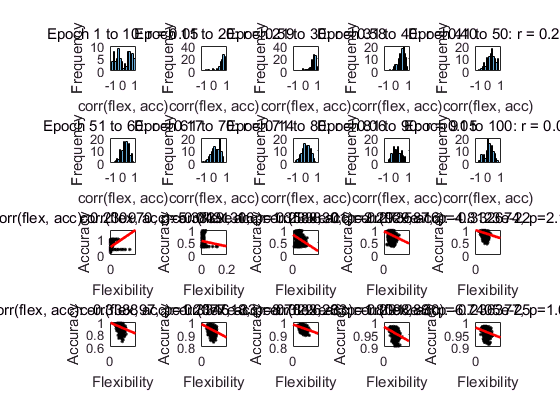



% visualize the degree distribution for individual difference and within subjects
% visualize the relationship between accuracy and flexibility separately




epochDiff = 10;
nEpochWinSize = epochEarlystop / epochDiff;

flex_acc_pair = cell(nEpochWinSize,1);
modu_acc_pair = cell(nEpochWinSize,1);

flex_acc_corr = zeros(120,nEpochWinSize);
modu_acc_corr = zeros(120,nEpochWinSize);


for k = 1:length(flex_acc_pair)
    flex_acc_pair{k} = [0,0];
    modu_acc_pair{k} = [0,0];
    epochStart = 1 + epochDiff*(k-1);
    epochEnd= epochDiff*k;
    for i = 1:120
        flex_acc_pair{k} = cat(1, flex_acc_pair{k},[dataFile_R_5_rep_120_diff_data{i}.flexibility(epochStart:epochEnd),dataFile_R_5_rep_120_diff_data{i}.acc(epochStart:epochEnd)]);
        flex_acc_corr(i,k) = corr(dataFile_R_5_rep_120_diff_data{i}.flexibility(epochStart:epochEnd), dataFile_R_5_rep_120_diff_data{i}.acc(epochStart:epochEnd));
        
        modu_acc_pair{k} = cat(1, modu_acc_pair{k},[dataFile_R_5_rep_120_diff_data{i}.modularity(epochStart:epochEnd),dataFile_R_5_rep_120_diff_data{i}.acc(epochStart:epochEnd)]);
        modu_acc_corr(i,k) = corr(dataFile_R_5_rep_120_diff_data{i}.modularity(epochStart:epochEnd), dataFile_R_5_rep_120_diff_data{i}.acc(epochStart:epochEnd));    
    end
    flex_acc_pair{k} = flex_acc_pair{k}(2:end,:);
    modu_acc_pair{k} = modu_acc_pair{k}(2:end,:);
end
colNum = nEpochWinSize/2;
figure;
for i = 1:nEpochWinSize
    %figure;
    %set(gcf,'position',[0,0,600,1000]); 
    subplot(4,colNum,i);
    histogram(flex_acc_corr(:,i),'NumBins',20,'Normalization','probability');
    axis square;
    title(sprintf('Epoch %d to %d: r = %.2f', 1 + epochDiff*(i-1), epochDiff*i, nanmean(flex_acc_corr(:,i))));
    xlabel('Correlation');
    ylabel('Probability');
    xlim([-1,1]);
    set(gca,'FontSize',10);


    subplot(4,colNum,i+nEpochWinSize);
    scatter(flex_acc_pair{i}(:,1), flex_acc_pair{i}(:,2),'black', '.'); hold on;
    hls = lsline;
    hls.Color = 'r';
    hls.LineWidth = 2;
    axis square;
    [rtmp, ptmp] = corr(flex_acc_pair{i}(:,1), flex_acc_pair{i}(:,2));
    title(sprintf('corr(flex, acc): %f, p=%.4e', rtmp,ptmp));
    xlabel('Flexibility');
    ylabel('Accuracy');
    set(gca,'FontSize',10);
    box on;
end

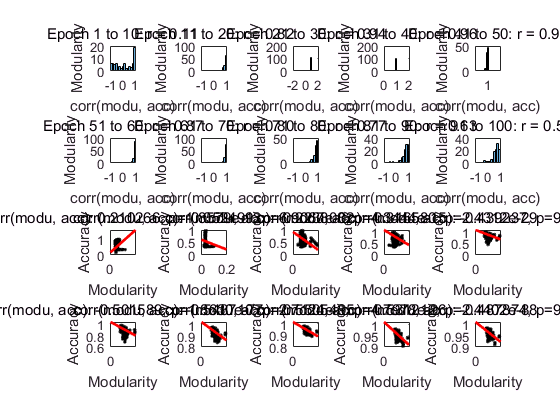


figure;
for i = 1:nEpochWinSize
    %figure;
    %set(gcf,'position',[0,0,600,1000]); 
    subplot(4,colNum,i);
    histogram(modu_acc_corr(:,i),'NumBins',20,'Normalization','probability');
    axis square;
    title(sprintf('Epoch %d to %d: r = %.2f', 1 + epochDiff*(i-1), epochDiff*i, nanmean(modu_acc_corr(:,i))));
    xlabel('Correlation');
    ylabel('Probability');
    xlim([-1,1]);
    set(gca,'FontSize',10);


    subplot(4,colNum,i+nEpochWinSize);
    scatter(modu_acc_pair{i}(:,1), modu_acc_pair{i}(:,2),'black', '.'); hold on;
    hls = lsline;
    hls.Color = 'r';
    hls.LineWidth = 2;
    axis square;
    [rtmp, ptmp] = corr(modu_acc_pair{i}(:,1), modu_acc_pair{i}(:,2));
    title(sprintf('corr(modu, acc): %f, p=%.4e', rtmp,ptmp));
    xlabel('Modularity');
    ylabel('Accuracy');
    set(gca,'FontSize',10);
    box on;
end

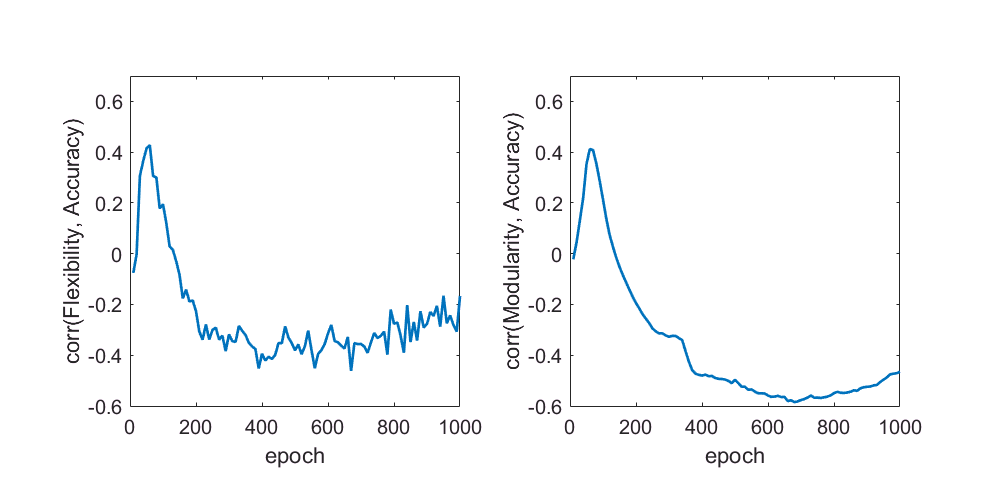






% visualize the correlation within the epoch across Time and Instance in
% two types
% visualize for Type I
corr_acc_flex_type1 = zeros(epochEarlystop,1);
corr_acc_modu_type1 = zeros(epochEarlystop,1);
for i  = 1:epochEarlystop
    corr_acc_flex_type1(i) = corr(type_1_acc_stack(i,:)', type_1_flex_stack(i,:)');
    corr_acc_modu_type1(i) = corr(type_1_acc_stack(i,:)', type_1_modu_stack(i,:)');
end

figure;
set(gcf,'position',[0,0,1000,500]);
subplot(1,2,1);
plot((1:epochEarlystop)*10, corr_acc_modu_type1,'LineWidth',2);
ylim([-0.6, 0.7]);
xlabel('epoch');
ylabel('corr(Modularity, Accuracy)');
axis square;
set(gca,'FontSize',15);

subplot(1,2,2);
plot((1:epochEarlystop)*10, corr_acc_flex_type1,'LineWidth',2);
hold on;
plot((1:epochEarlystop)*10, corr_acc_modu_type1,'LineWidth',1);
ylim([-0.6, 0.7]);
xlabel('epoch');
% ylabel('corr(Modularity, Accuracy)');
ylabel('Correlation');
legend({'Flexibility','Modularity'});
axis square;
set(gca,'FontSize',15);

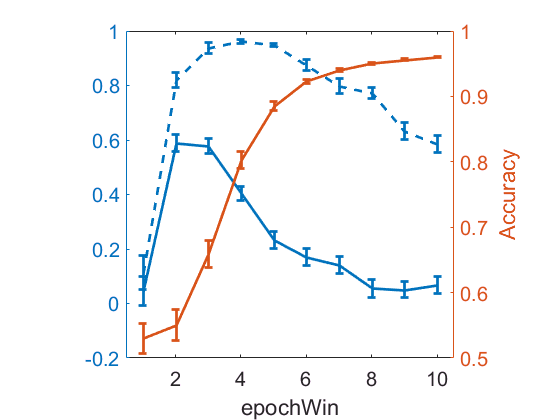









for i = 1:10
    accFlexWinMean(i) = nanmean(flex_acc_pair{i}(:,2));
    accModuWinMean(i) = nanmean(modu_acc_pair{i}(:,2));
    accFlexWinStdErr(i) = nanstd(flex_acc_pair{i}(:,2))/sqrt(120);
    accModuWinStdErr(i) = nanstd(modu_acc_pair{i}(:,2))/sqrt(120);
end



figure;
yyaxis left;
errorbar(nanmean(flex_acc_corr),nanstd(flex_acc_corr)/sqrt(120), 'LineWidth',2, 'MarkerEdgeColor','blue'); hold on;
errorbar(nanmean(modu_acc_corr),nanstd(modu_acc_corr)/sqrt(120), 'LineWidth',2, 'MarkerEdgeColor','yellow');
xlim([0.5,10.5]);
yyaxis right;
errorbar(accFlexWinMean, accFlexWinStdErr, 'LineWidth',2);
ylabel('Accuracy');
xlabel('epochWin');
set(gca,'FontSize',15);
axis square;

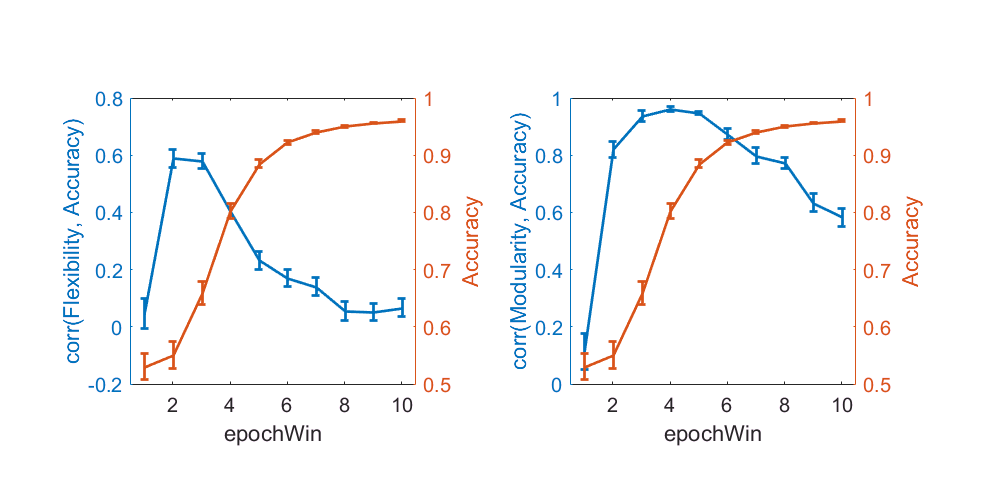




figure;
set(gcf,'position',[0,0,1000,500]);
subplot(1,2,1);
yyaxis left;
errorbar(nanmean(flex_acc_corr),nanstd(flex_acc_corr)/sqrt(120), 'LineWidth',2);
xlim([0.5,10.5]);
ylabel('corr(Flexibility, Accuracy)');
yyaxis right;
errorbar(accFlexWinMean, accFlexWinStdErr, 'LineWidth',2);
ylabel('Accuracy');
xlabel('epochWin');
set(gca,'FontSize',15);
axis square;

subplot(1,2,2);
yyaxis left;
errorbar(nanmean(modu_acc_corr),nanstd(modu_acc_corr)/sqrt(120), 'LineWidth',2);
xlim([0.5,10.5]);
ylabel('corr(Modularity, Accuracy)');
yyaxis right;
errorbar(accModuWinMean, accModuWinStdErr, 'LineWidth',2);
ylabel('Accuracy');
xlabel('epochWin');
set(gca,'FontSize',15);
axis square;

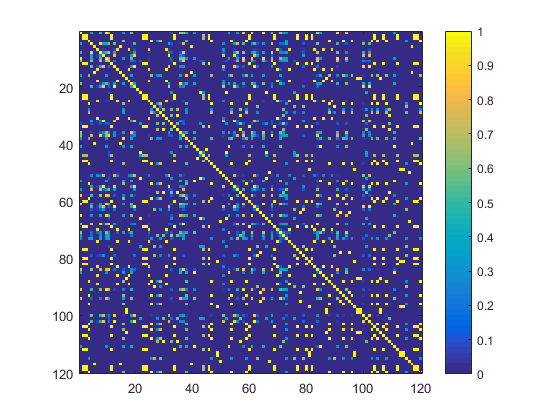






% axis square; 
% visualize the modular structure
% nNode x nNode x Epoch, reoeats
load('allegiance.mat');
for i = 1:120
    allegianceMatrix{i} = allegianceMatrix{i}(:,:,1:epochEarlystop);
end
figure;
imagesc(allegianceMatrix{1}(:,:,12));
colorbar; axis square;

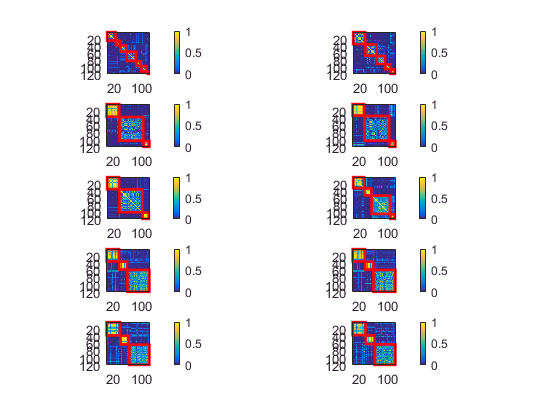


cPartition = {};
allegiance = {};
modularityValue = [];

for i = 1:120
    for j = 1:10
        allegianceMatrixWin{i}(:,:,j) = nanmean(allegianceMatrix{i}(:,:,1+10*(j-1):10*j), 3);
    end
end

iddx = 2;
figure;
for i = 1:10
    gplus = 1.00;
    Acell{1} = squeeze(allegianceMatrixWin{iddx}(:,:,i));
    [cPartition{i}, allegiance{i}, modularityValue(i)] = genRobustCommunityFromASeries(Acell,gplus,1.0);
    subplot(5,2,i);
    plotCommunities(Acell{1},cPartition{i},2); axis square; colorbar;
end

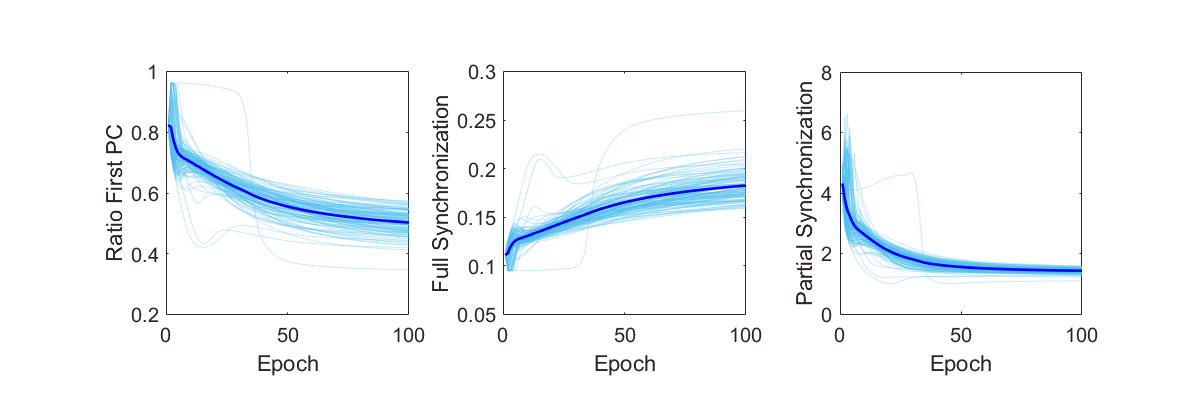








% examine the sparsity, entropy, synchronization
load('sigValCorr.mat');
ratioFirst = zeros(120,100);
syncronWithFirst = zeros(120,100);
syncronNoFirst = zeros(120,100);
for i = 1:120
    for j = 1:100
        colSlice = squeeze(sigCov{i}(:,j));
        ratioFirst(i,j) = colSlice(1)/120;
        syncronWithFirst(i,j)  = 1/std(colSlice);
        syncronNoFirst(i,j) = 1/std(colSlice(2:end));
    end
end

figure;
set(gcf,'position',[0,0,1200,400]); 
subplot(1,3,1);
for i = 1:120
    ll = plot(ratioFirst(i,:),'cyan');
    ll.Color = [0.3010, 0.7450, 0.9330, 0.3];hold on;
end
plot(mean(ratioFirst,1),'blue','LineWidth',2);
ylabel('Ratio First PC');
xlabel('Epoch');
set(gca,'FontSize',15);
axis square;

subplot(1,3,2);
for i = 1:120
    ll = plot(syncronWithFirst(i,:),'cyan');
    ll.Color = [0.3010, 0.7450, 0.9330, 0.3];hold on;
end
plot(mean(syncronWithFirst,1),'blue','LineWidth',2);
ylabel('Full Synchronization');
xlabel('Epoch');
set(gca,'FontSize',15);
axis square;


subplot(1,3,3);
for i = 1:120
    ll = plot(syncronNoFirst(i,:),'cyan');
    ll.Color = [0.3010, 0.7450, 0.9330, 0.3];hold on;
end
plot(mean(syncronNoFirst,1),'blue','LineWidth',2);
ylabel('Partial Synchronization');
xlabel('Epoch');
set(gca,'FontSize',15);
axis square;

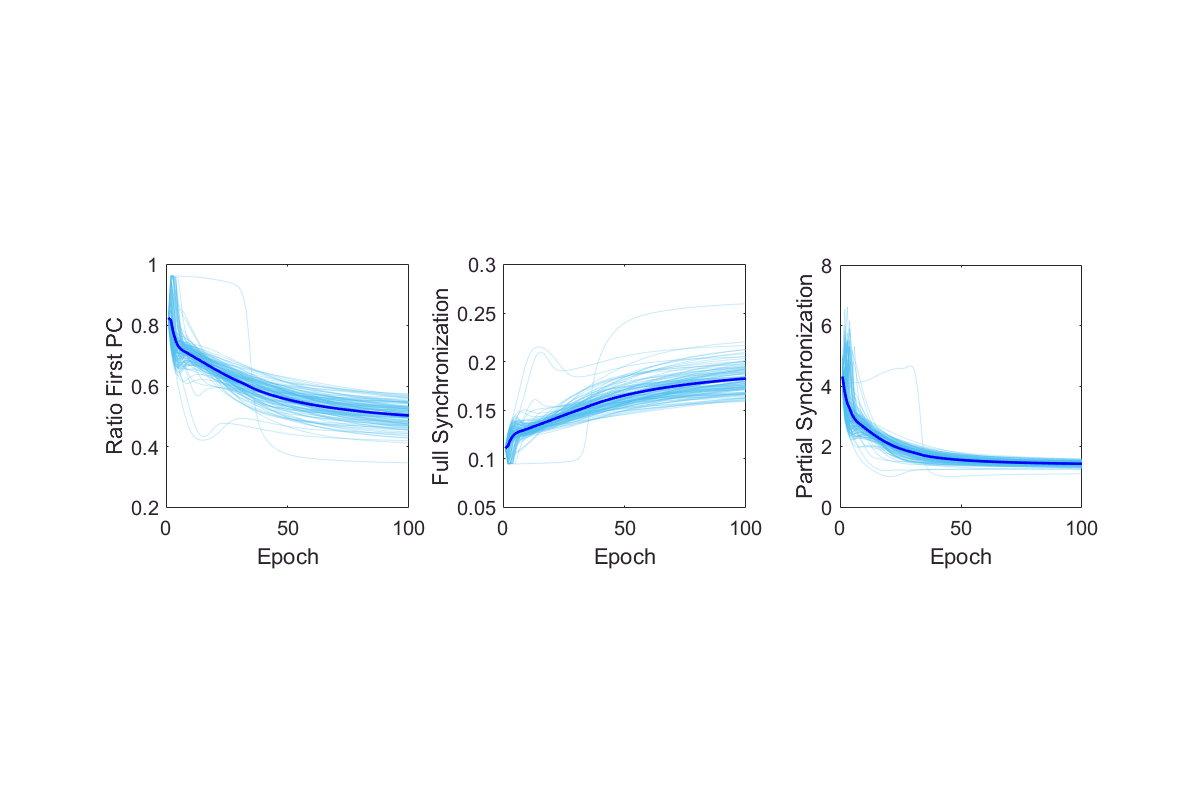




figure;
% plot for type I
set(gcf,'position',[0,0,1200,800]); 
subplot(1,3,1);
for i = 1:120
    if accCurveType(i) == 1
        ll = plot(ratioFirst(i,:),'cyan'); 
        ll.Color = [0.3010, 0.7450, 0.9330, 0.3];hold on;
    end
end
plot(mean(ratioFirst(accCurveType==1,:),1),'blue','LineWidth',2);
ylabel('Ratio First PC');
xlabel('Epoch');
set(gca,'FontSize',15);
axis square;

subplot(1,3,2);
for i = 1:120
    if accCurveType(i) == 1
        ll = plot(syncronWithFirst(i,:),'cyan'); 
        ll.Color = [0.3010, 0.7450, 0.9330, 0.3];hold on;
    end
end
plot(mean(syncronWithFirst(accCurveType==1,:),1),'blue','LineWidth',2);
ylabel('Full Synchronization');
xlabel('Epoch');
set(gca,'FontSize',15);
axis square;


subplot(1,3,3);
for i = 1:120
    if accCurveType(i) == 1
        ll = plot(syncronNoFirst(i,:),'cyan'); 
        ll.Color = [0.3010, 0.7450, 0.9330, 0.3];hold on;
    end
end
plot(mean(syncronNoFirst(accCurveType==1,:),1),'blue','LineWidth',2);
ylabel('Partial Synchronization');
xlabel('Epoch');
set(gca,'FontSize',15);
axis square;